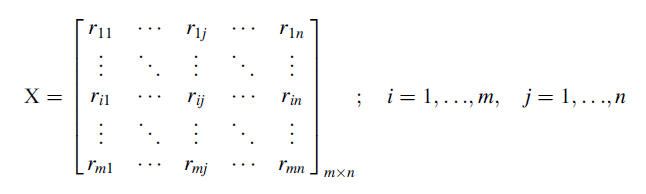

Create decision matrix. i = dominated individual, j = attribution (IPF & SEA)

decisionmatrix = [paretofront(:,1) -1.*paretofront(:,2)];

Decision matrix normalization are then conduct in EACH attribute. Normalize can be done by dividing each element in decision matrix by the sum of its individual in an attribute.

sumcriteria = sum(decisionmatrix);
normalizedecisionmatrix = [decisionmatrix(:,1)/sumcriteria(1,1) , decisionmatrix(:,2)/sumcriteria(1,2)];

Normalized decision matrix are then weighted where *wj* is the weight of attribute.

IPFweight = 0.3220;
SEAweight = 0.6780;
normIPFmat = normalizedecisionmatrix(:,1)*IPFweight;
normSEAmat = normalizedecisionmatrix(:,2)*SEAweight;

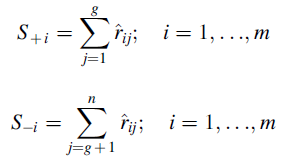

The negative and positve type of attribute, IPF and SEA respectively, are then calculated. Where g = number of positive attribute and n = number of negative attribute.

negativeS = normIPFmat;
positiveS = normSEAmat;

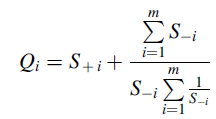

The Relative Significance Value (Q) of each individual is calculated by using the positiveS individual (S+i), negativeS individual (S-i), summation of negativeS matrix (sum all individual from negative attribute), and summation of inverse element in negativeS matrix.

negativesum = sum(negativeS);
negativefracsum= sum((1./negativeS));

for i = 1:size(negativeS) 
  Q(i,1) = positiveS(i) + ((negativesum)/(negativeS(i)*negativefracsum));
end

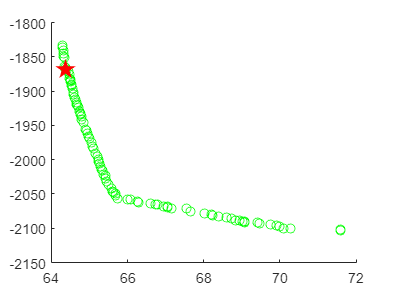

[maxQ,indexQ] = max(Q);
scatter(paretofront(:,1),paretofront(:,2),'green'); hold on;
scatter(paretofront(indexQ,1),paretofront(indexQ,2),200,'rp','filled');